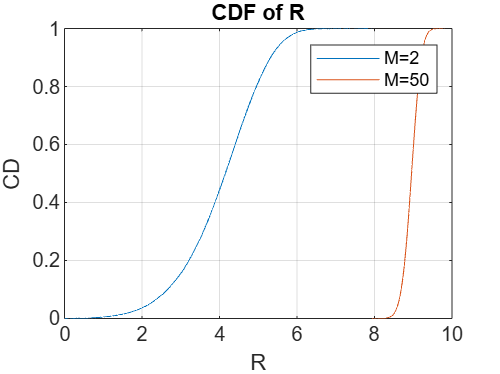

Mc = 2;              % Number of transmit antennas
P = 10;             % Transmit power
N = 1e5;            % Number of realizations


h_real = normrnd(0,1,[N Mc]) / sqrt(2);
h_imag = normrnd(0,1,[N Mc]) / sqrt(2);

h = h_real + 1j * h_imag;

norm_h_squared = sum(abs(h).^2, 2);

Rc = log2(1 + P * norm_h_squared);

Me=50;

h_real = normrnd(0,1,[N Me]) / sqrt(2);
h_imag = normrnd(0,1,[N Me]) / sqrt(2);

h = h_real + 1j * h_imag;

norm_h_squared = sum(abs(h).^2, 2);

Re = log2(1 + P * norm_h_squared);

cdfplot(Rc);

hold on;

cdfplot(Re);
title('CDF of R')
xlabel('R')
ylabel('CD')
legend('M=2','M=50')